close all
load RawData\'1T-TaS2(point defect)'\lattCoord.mat
clearvars -except mapCD
addpath myFunction\myftn\
fn = 'RawData\1T-TaS2(point defect)\mapCD.mat';
loadif(fn);

fldNm = 1×1 cell array
    {'mapCD'}



Your variables are:

fldNm  fn     mt     



ans = 'already'

## Test the floating error of fft

f1 = figure(1)

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


figure(1).Visible

ans =   OnOffSwitchState enumeration

    off


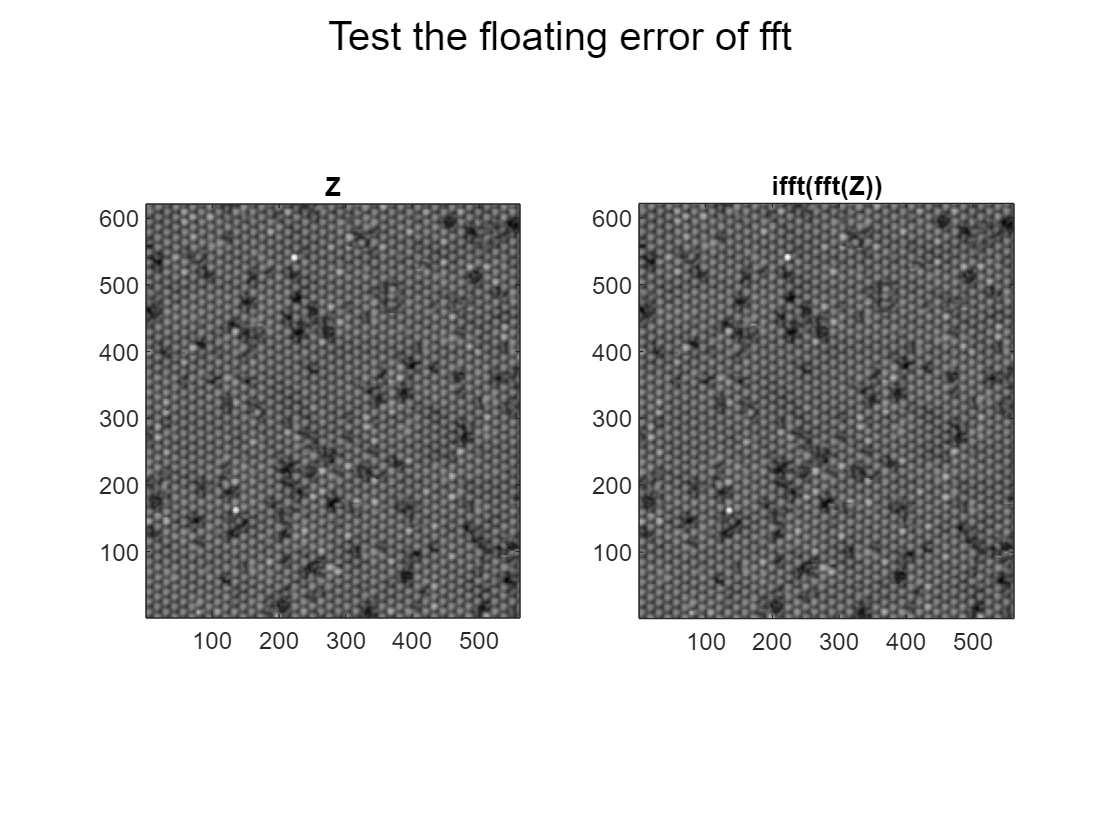

Z = mapCD.dt(1).Z;
Zr = ifft2(fft2(Z));
subplot(1,2,1)
views(Z)
title('Z')
colormap gray
subplot(1,2,2)
views(Zr)
title('ifft(fft(Z))')
colormap gray
sgtitle('Test the floating error of fft')

% annotation("textbox", [0.4397 0.8497 0.1 0.1], "String", "dddd")

## Test the floating error of fft 2

f2 = figure(2)

f2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


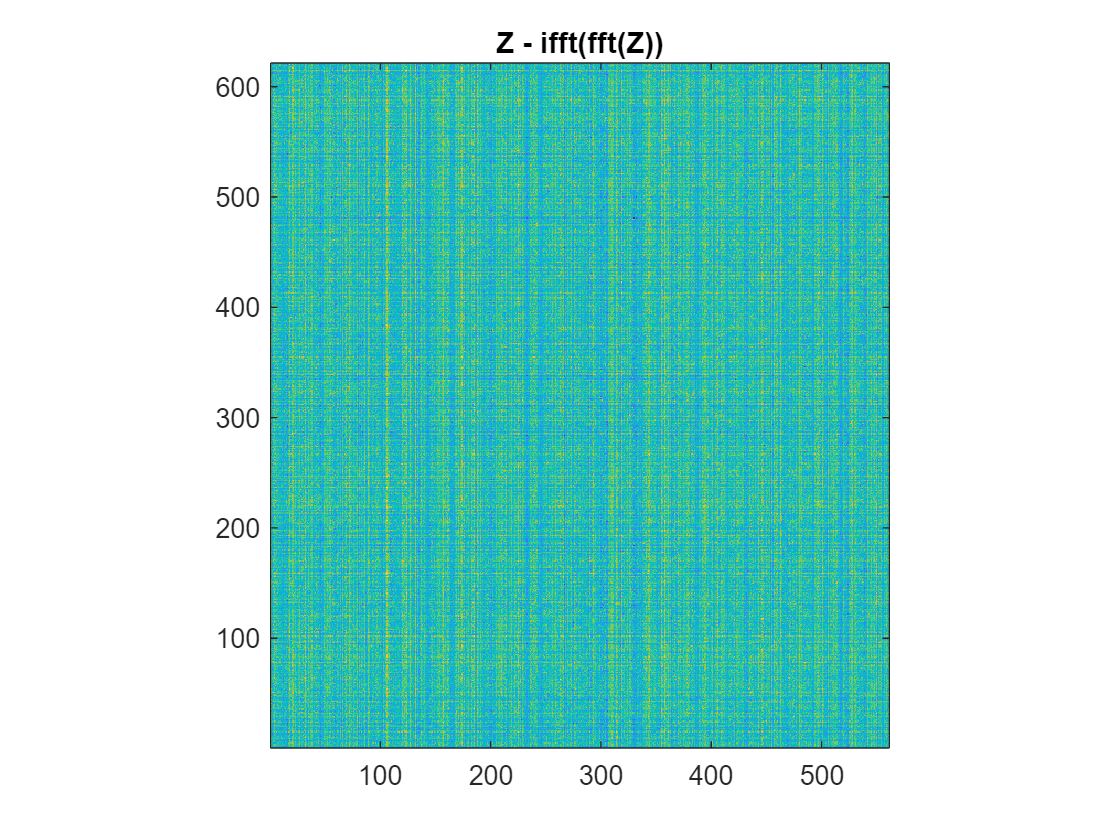

noise = Z-Zr;
views(noise)
title('Z - ifft(fft(Z))')

SNR = mean(mean(Z))/std(noise(:))

SNR = 2.5165e+15

## Masked FFT filter

Cal

graphic

f_maskedFFT = figure(3);
f= f_maskedFFT;
msb = 2

msb = 2

nsb = 3

nsb = 3

p=0

p = 0

for isb = 1:msb
    for jsb = 1:nsb
        p = p + 1;
        sbs(isb,jsb)=subplot(msb,nsb,p)
    end
end

sbs =   2×3 Axes array:

    Axes    Axes    Axes
    Axes    Axes    Axes


sbs =   2×3 Axes array:

    Axes    Axes    Axes
    Axes    Axes    Axes


sbs =   2×3 Axes array:

    Axes    Axes    Axes
    Axes    Axes    Axes


sbs =   2×3 Axes array:

    Axes    Axes    Axes
    Axes    Axes    Axes


sbs =   2×3 Axes array:

    Axes    Axes    Axes
    Axes    Axes    Axes


sbs =   2×3 Axes array:

    Axes    Axes    Axes
    Axes    Axes    Axes


sgtitle('filtered FFT')
f.CurrentAxes = sbs(1,1)

f =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


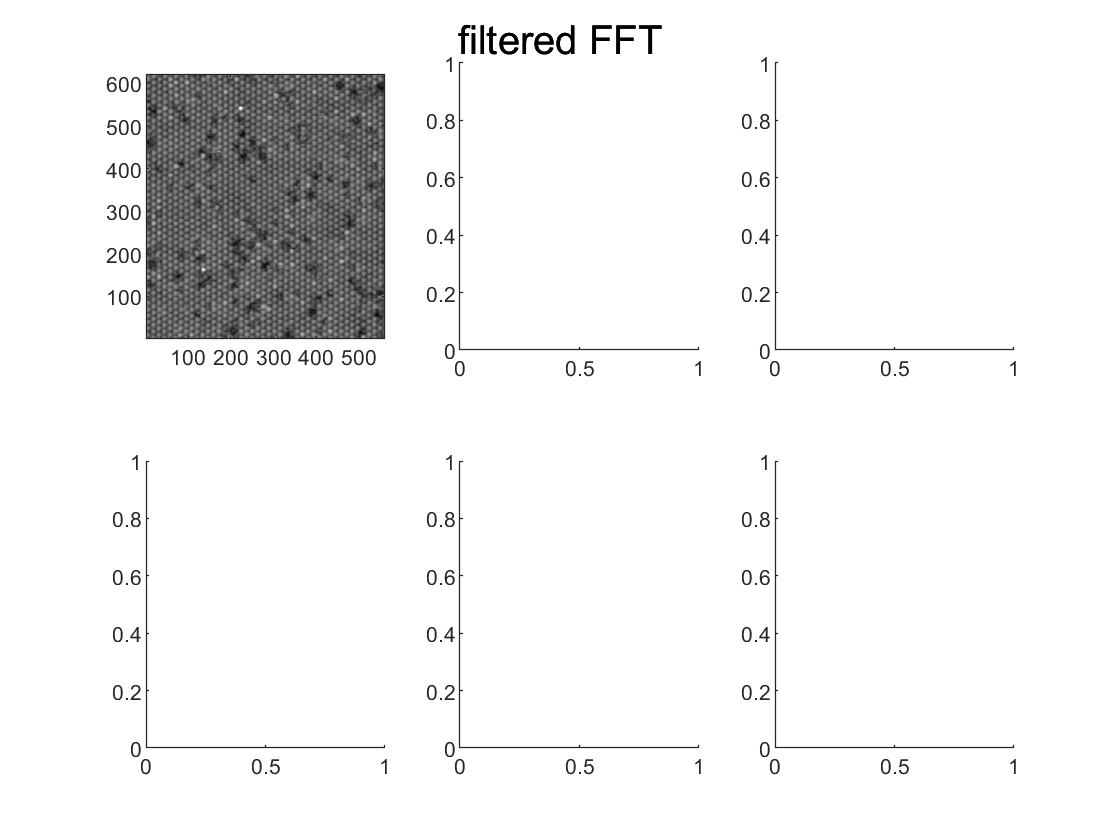

views(Z)
colormap(gray)

f.Visible ="on"

f =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


f1.Visible

ans =   OnOffSwitchState enumeration

    off


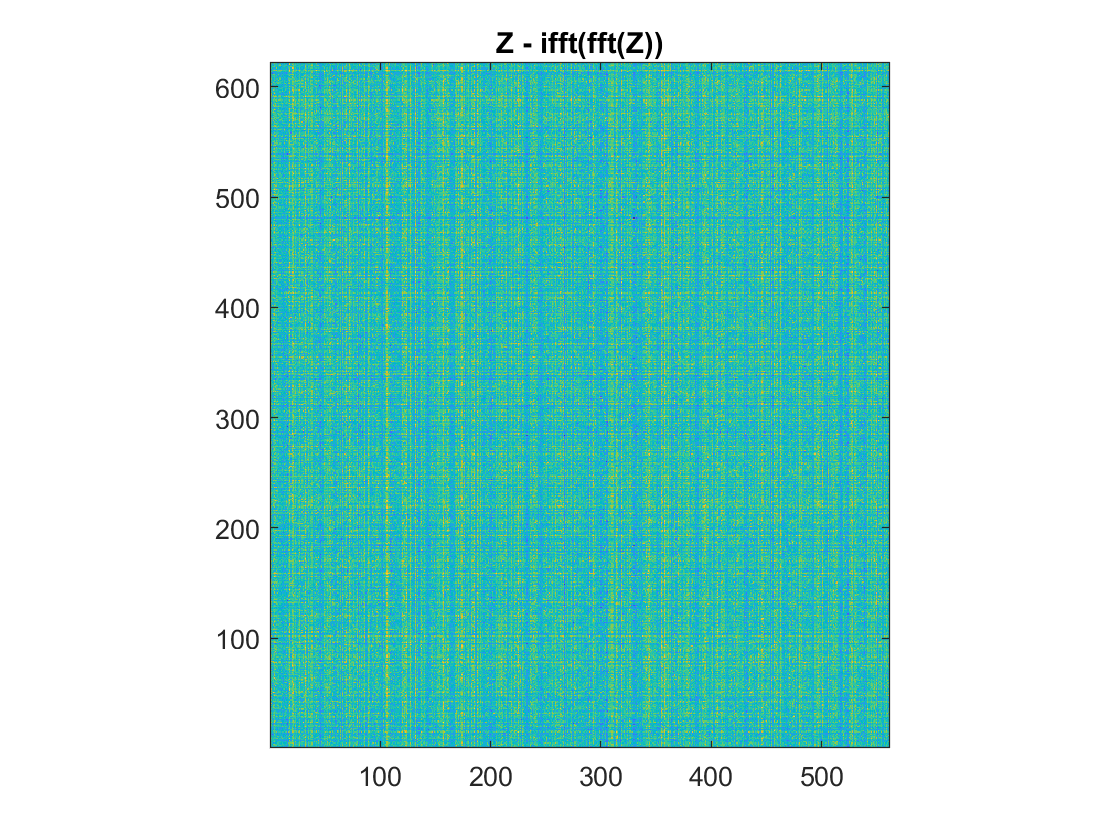

f2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


f2.Visible ="on"